%% Simulation of linear system of monocopter with flaps 
clc
clear all
close all

load gyro_x_flap.mat
load gyro_y_flap.mat
load ka_flap.mat
load ka_flap_NDI.mat

%% Parameters
J = 3.2284E-6; % moment of inertia of the rotor
b = 3.5077E-6; % motor viscous friction constant 
K = 0.0274; % electromotive force constant, motor torque constant 
R = 4; % electric resistance 
L = 2.75E-6; % electric inductance  
Jxx = 0.00077; % symmetrical so jxx = jyy
Jzz = 0.0095723985;
pitch = 41;
pitch = abs(pitch);
plot_variable = 1;
% (bod pitch * ka * servo pitch) contributes to lift force for disk torque
ka = 0.01; % .01,.03,.05,.07,.09,.11,.13
ka = ka*plot_variable; % x1, x2, x3, x4, x5...all the way to x13, default is x 10
rps = -22.0440

rps = -22.0440

rps_squared = rps^2;
cl = 0.11;
cd = 0.023; 
g = 9.81;
rho = 1.225;
radius = 0.61;
chord_length = 0.1;
mass = 0.16;
torque_w_mass = radius*((cl*pitch*ka*rps_squared*rho*chord_length*(radius^3))/(6));
drag_rotation = (cd*pitch*ka*rps_squared*rho*chord_length*(radius^3))/(6*mass);
com = 1/((g + drag_rotation)); % omega abt x is positive (pitch), omega abt y is negative (roll)
linesize = 2;
Fontsize = 10;

t = 0:0.01:5;
u = sin((2.5*t)-(pi)); % omega abt x, linear acc y
%u = sin((2.2*t)-(pi/2)); % omega abt y, linear acc x

%% servo and angular acceleration feedback
omega_dot = torque_w_mass/Jxx;
s = tf('s');
servo = K/(s*((J*s+b)*(L*s+R)+K^2)); % includes the integral to positional angle alrd
H_servo = 1;
H_omega_dot_tf = 1; % lpf is needed and tuned here for indi, ndi is better only  
stf = servo/(1+(servo*H_servo));
%isstable(stf)
%pole(stf)
%omega_dot_tf = stf; % ndi
omega_dot = stf*omega_dot;
% omega_dot_tf = omega_dot/(1+(omega_dot*H_omega_dot_tf)); % indi
% isstable(omega_dot_tf)
% pole(omega_dot_tf)

%[omega_dot_controller,info] = pidtune(omega_dot,'PID');
omega_dot_tf = feedback(omega_dot,1); % implement feedback for tf which is servo to become servo/(1+(servo*H)

% to simulate step input of a single servo angle
% t = 0:0.001:0.3;
% Config = RespConfig('Amplitude',5);
% step(omega_dot_tf, t, Config) % step function here is in the form of a servo angle 
% ylabel('Position, \theta (radians)')
% title('Response to a Step Reference')
%legend('Kp = 1',  'Kp = 11',  'Kp = 21')

%% to simulate disturbance step input

% [omega_dot_pi,info_d] = pidtune(stf*torque_w_mass,'PID')
% disturbance_torque_tf = ((1/Jxx)*(1-(H_omega_dot_tf*omega_dot_pi*stf*torque_w_mass)));
% t = 0:0.001:0.2;
% Config = RespConfig('Amplitude',5);
% step(disturbance_torque_tf, t, Config) % step function here is in the form of a servo angle 
% ylabel('omega_dot_tf')
% title('Response to a Step Disturbance')

% snap
snap = (s^2)*com*omega_dot*(1/(s^2))*1/com; % snap only
[snap_controller,snap_info] = pidtune(snap,'PD'); % controller only needed for omega abt y, linear acc x
snap_tf = feedback(snap,1); % jerk and snap INDI

snap = lsim(snap_tf,u,t); % INDI cant be tested

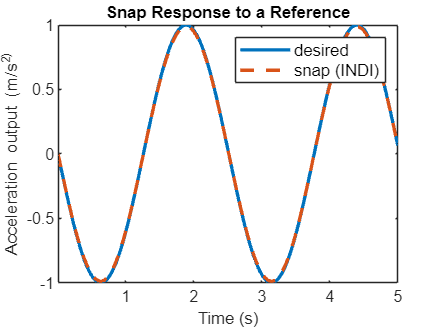

plot (t,u,'LineWidth',linesize)
hold on
plot(t,snap,'lineStyle','--','LineWidth',linesize)
hold off
xlim([0.011 5])

ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Snap Response to a Reference','FontSize',Fontsize)
legend('desired','snap (INDI)','FontSize',Fontsize)

% snap + jerk
D = 0*plot_variable; 
omega = (s+D)*com*omega_dot_tf*(1/(s^2))*1/com; % jerk only
[omega_controller,omega_info] = pidtune(omega,'P',0.001)

omega_controller =
 
  Kp = 0.00101
 
P-only controller.
Model Properties


omega_info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.0000e-03
           PhaseMargin: 90.0000


omega_tf_ndi = omega; % jerk and snap NDI
omega_tf = feedback(omega_controller*omega,1); % jerk and snap INDI

jerk = lsim(omega_tf,u,t);

jerk_ndi = lsim(omega_tf_ndi,u,t);

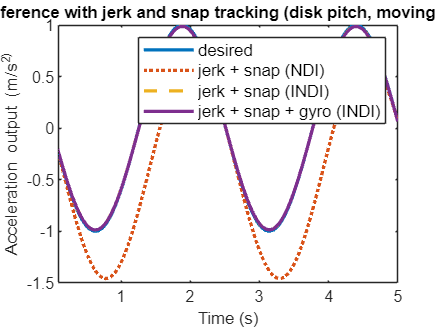

plot (t,u,'LineWidth',linesize)
hold on
plot(t,jerk_ndi + snap,'lineStyle',':','LineWidth',linesize)
plot(t,jerk+snap,'lineStyle','--','LineWidth',linesize)
plot(t,jerk+snap+gyro_y_flap,'LineWidth',linesize) % linear acc y
%plot(t,jerk+snap+gyro_x_flap,'LineWidth',linesize) % linear acc x
hold off
xlim([0.1 5])

ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Response to a reference with jerk and snap tracking (disk pitch, moving along world y axis)','FontSize',Fontsize)
%title('Response to a reference with jerk and snap tracking (disk roll, moving along world x axis)','FontSize',Fontsize)
legend('desired','jerk + snap (NDI)','jerk + snap (INDI)','jerk + snap + gyro (INDI)','FontSize',Fontsize)

% quat
angle = com*omega_dot_tf*(1/(s^2))*1/com;
[angle_controller,angle_info] = pidtune(angle,'PD',10)

angle_controller =
 
             
  Kp + Kd * s
             

  with Kp = 50.3, Kd = 8.78
 
Continuous-time PD controller in parallel form.
Model Properties


angle_info = struct with fields:
                Stable: 1
    CrossoverFrequency: 10
           PhaseMargin: 60.0000


angle_tf = feedback(angle_controller*angle,1);
angle_tf_ndi = angle_controller*angle;

quat = lsim(angle_tf,u,t);

quat_ndi = lsim(angle_tf_ndi,u,t);

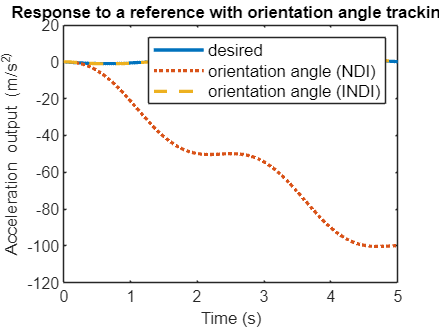

plot (t,u,'LineWidth',linesize)
hold on
plot(t,quat_ndi,'lineStyle',':','LineWidth',linesize)
plot(t,quat,'lineStyle','--','LineWidth',linesize)
hold off

ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Response to a reference with orientation angle tracking','FontSize',Fontsize)
legend('desired','orientation angle (NDI)','orientation angle (INDI)','FontSize',Fontsize)

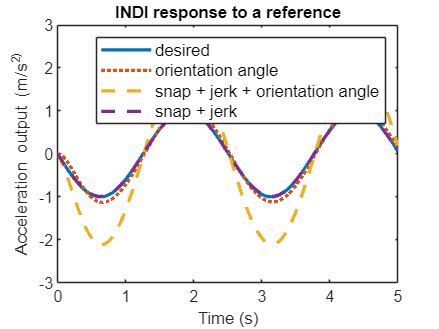

% all together
plot (t,u,'LineWidth',linesize)
hold on
plot(t,quat,'lineStyle',':','LineWidth',linesize)
plot(t,jerk+snap+quat,'lineStyle','--','LineWidth',linesize)
plot(t,jerk+snap,'lineStyle','--','LineWidth',linesize) % no quat here = the best
hold off

ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('INDI response to a reference','FontSize',Fontsize)
legend('desired','orientation angle','snap + jerk + orientation angle','snap + jerk','FontSize',Fontsize)



% gyro_y_flap = (((jerk+snap)*radius*Jxx))/(Jzz*rps); % add this to acc_y
% gyro_x_flap  = (-1*((jerk+snap)*radius*Jxx))/(Jzz*rps); % add this to acc_x



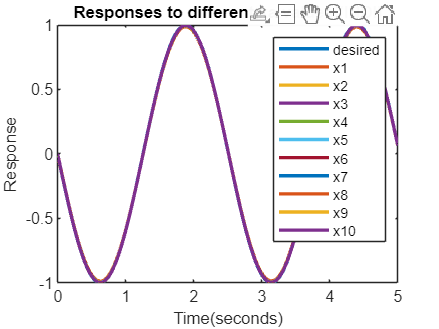

%ka_flap_values = zeros(501,10);
%ka_flap_values(:,plot_variable) = jerk+snap+gyro_y_flap;


plot (t,u,'LineWidth',linesize)
hold on
for i = 1:10
    plot(t,ka_flap_values(:,i),'LineWidth',linesize)
end    
hold off
ylabel('Response','FontSize',Fontsize)
xlabel('Time(seconds)','FontSize',Fontsize)
title('Responses to different ka values (INDI)','FontSize',Fontsize)
legend('desired','x1','x2','x3','x4','x5','x6','x7','x8','x9','x10') 

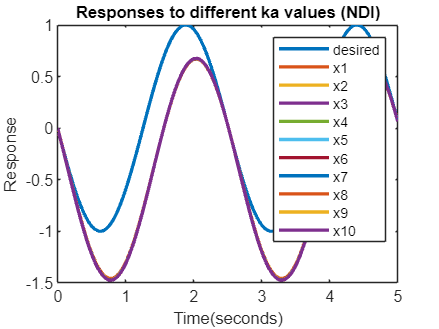

%ka_flap_values_NDI = zeros(501,10);
%ka_flap_values_NDI(:,plot_variable) = jerk_ndi+snap;

plot (t,u,'LineWidth',linesize)
hold on
for i = 1:10
    plot(t,ka_flap_values_NDI(:,i),'LineWidth',linesize)
end    
hold off
ylabel('Response','FontSize',Fontsize)
xlabel('Time(seconds)','FontSize',Fontsize)
title('Responses to different ka values (NDI)','FontSize',Fontsize)
legend('desired','x1','x2','x3','x4','x5','x6','x7','x8','x9','x10') 